% Test For second sound recording
%  Mumbai road bargaining

% Reading the audio
[samples, fsample] = audioread('TestAudio2.wav');

player = audioplayer(samples, fsample);
play(player);


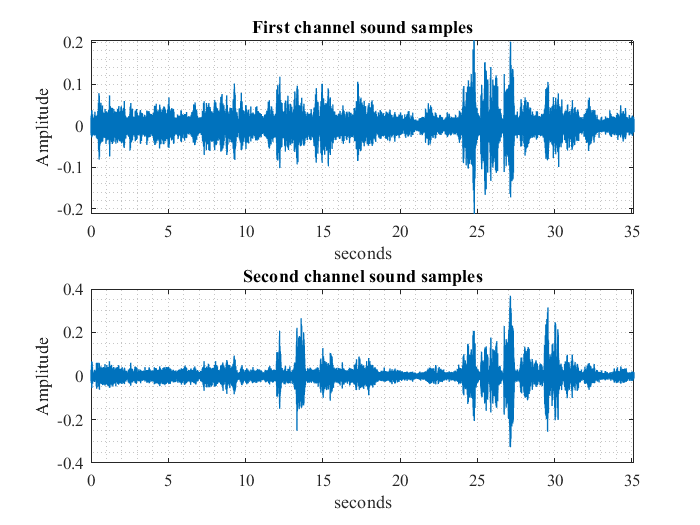

% Evidence handling and Initial assessment

% Waveform view
ShowWaveform(samples, fsample);

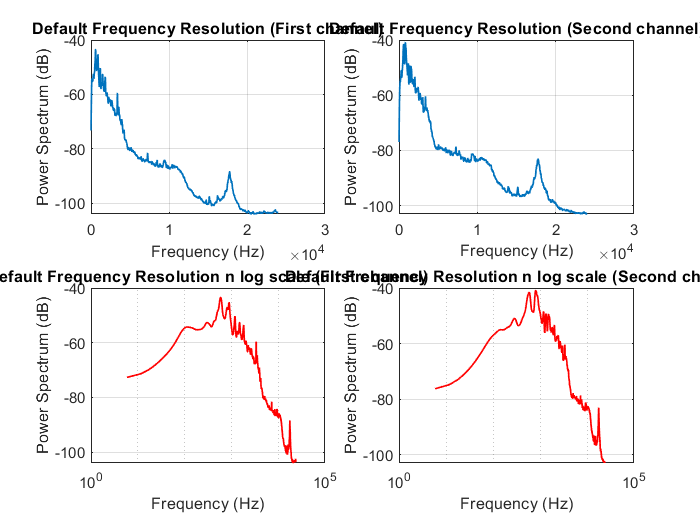


% PSD view
ShowPSD2(samples, fsample);


% Spectrogram view
% ShowSpectrogram(samples, fsample);

% Statistical view
audioStats(samples, fsample);

Max value in first Channel = 0.20584
Max value in second Channel = 0.36911
Minimum value in first Channel = -0.21213
Minimum value in second Channel = -0.32733
Mean value in first channel = -3.3392e-06
Mean value in second channel= -3.7489e-06
standard deviation of first channel= 0.017537
standard deviation of second channel= 0.025202
Variance of first channel= 0.00030753
Variance of second channel= 0.00063515
Power in first channel in dB= -35.1211
Power in second channel in dB= -31.9712
Sampling frequency in Hz =48000


% Audio feactures (MFCC)

% Mel Frequency capstral coefficient

[coeff, delta, deltaDelta, logf] = mfcc(samples, fsample);



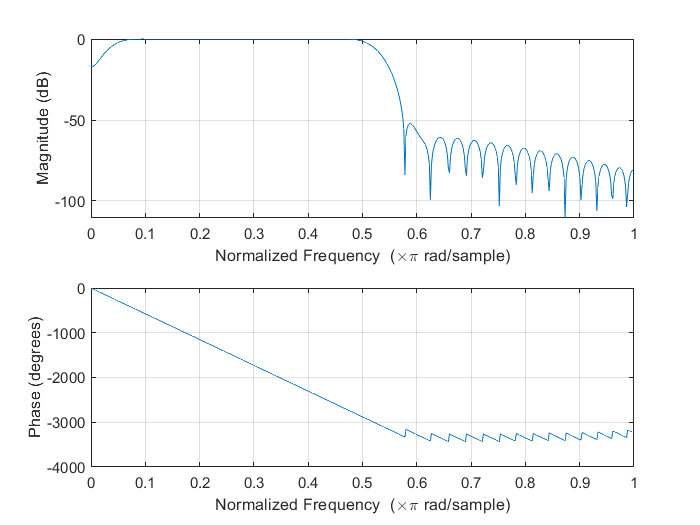

% Audio Enhancement techniques

% bandpass filter 
order =64;
resultAudio = bandpassVocalFilter(samples, order,fsample,0.5);

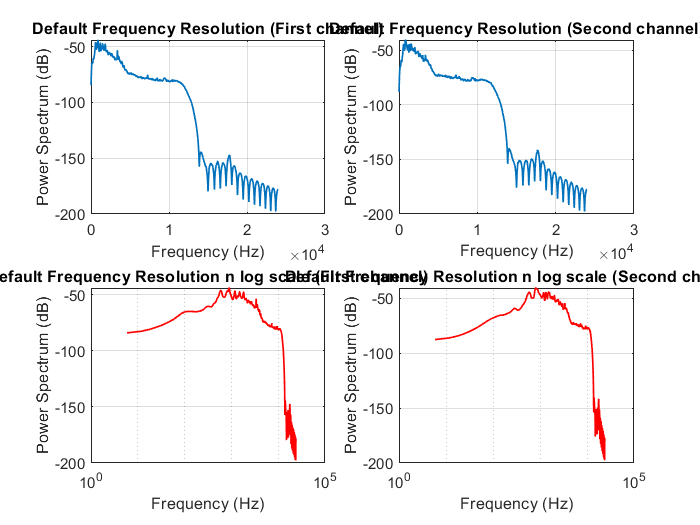


player = audioplayer(resultAudio, fsample);
play(player);

ShowPSD2(resultAudio, fsample);

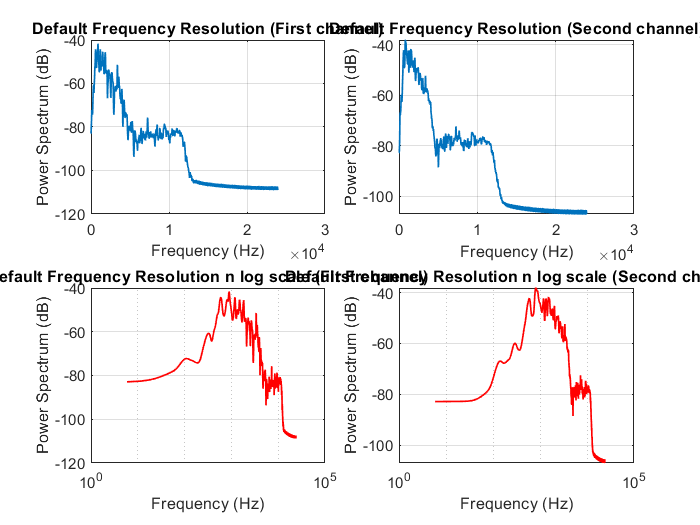


% Wiener filter approach

resultAudio2 = wienerFilter(resultAudio, fsample,0.10);
 
player = audioplayer(resultAudio2, fsample);
play(player);

ShowPSD2(resultAudio2, fsample);

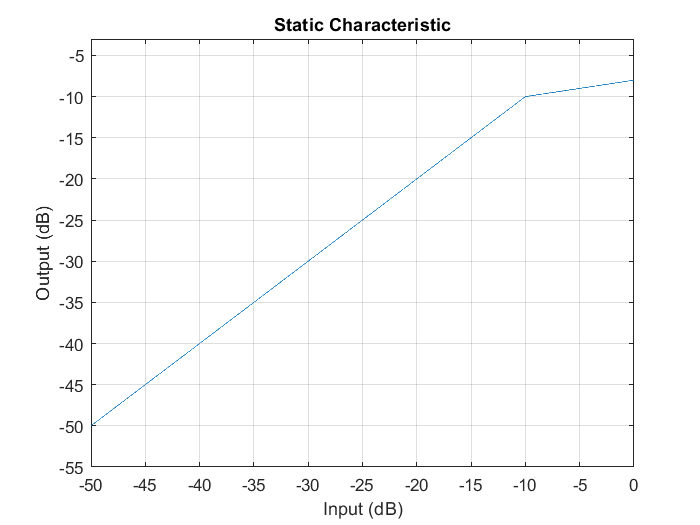

% Compressor 

dRC = compressor(-10,5,'SampleRate',fsample);
visualize(dRC)

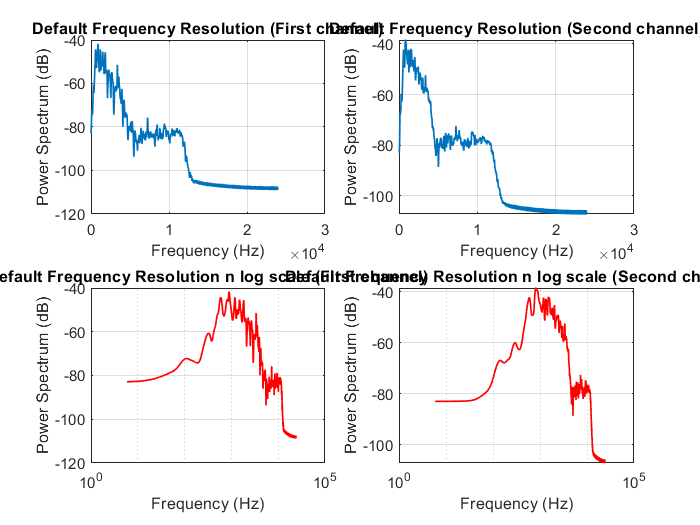


resultAudio3 = dRC(resultAudio2);

player = audioplayer(resultAudio3, fsample);
play(player);

ShowPSD2(resultAudio3, fsample);

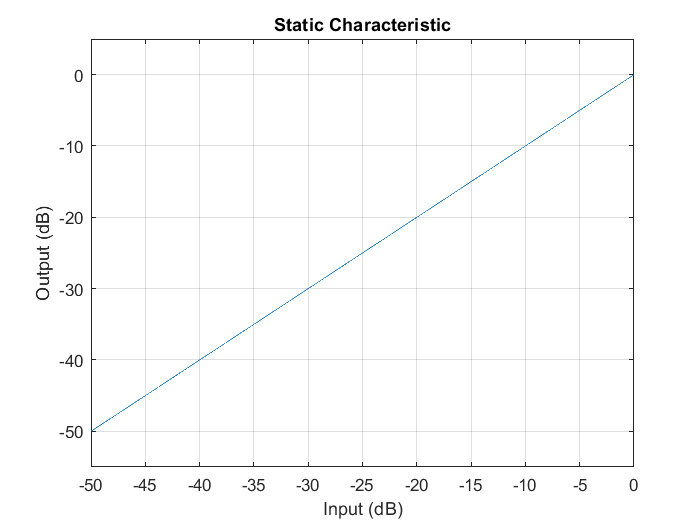

% Expender

dRC = expander(-100, 5, 'SampleRate',fsample);
visualize(dRC);

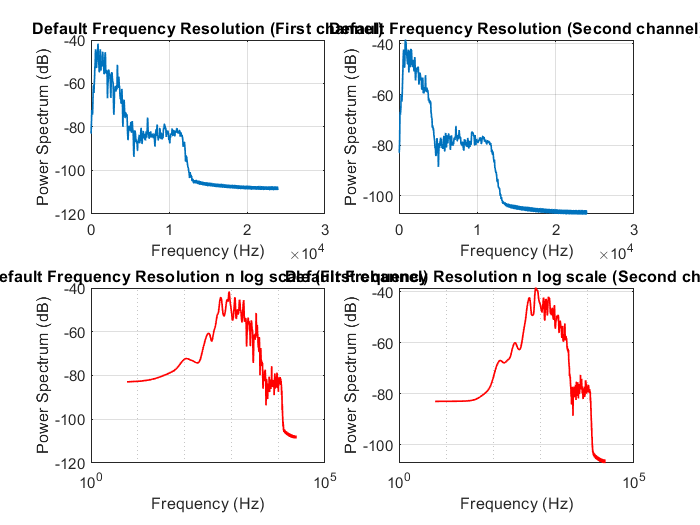


resultAudio4 = dRC(resultAudio3);


player = audioplayer(resultAudio4, fsample);
play(player);

ShowPSD2(resultAudio4, fsample);

audiowrite('enhancedTestAudio2.wav', resultAudio4, fsample);